% I = im2double(imread('cameraman.tif'));
I = im2double(imread('synthetic_data/ground_truth/manmade_01.png'));
% I = zeros(50,50);
% I(size(I,1)/2,size(I,2)/2)=255;

LEN = 43;
THETA = 45;
% PSF = fspecial('disk', 5);
PSF = fspecial('motion', LEN, THETA)

PSF =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0061    0.0163
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0061    0.0208    0.0061
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0061    0.0208    0.0061         0
         0         0         0         0         0         0 


% PSF2 = fspecial('motion',10,30)
% newPFS2 = zeros(size(PSF1))
% newPFS2(1:size(PSF2,1), 1:size(PSF2,2)) = PSF2

% blury_list = [];
% 
% for len = 20:2:28
%    for theta = 0:10:170
%        PSF1 = fspecial('motion', len, theta);
%        blurred = imfilter(I, PSF1, 'conv', 'circular');
%        blury_list = [blury_list, blurred];
%    end
% end

kernel1 = im2double(imread('synthetic_data/kernel/kernel_01.png'));
z1 = squeeze(kernel1(:,:,2))

z1 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0  



blurred1 = imfilter(I, z1)

blurred1 = blurred1(:,:,1) =

  Columns 1 through 999

    5.0349    6.4626    7.8571    9.1981   10.2888   11.1899   12.5099   15.5167   19.3939   22.8581   25.0293   25.1913   25.3981   25.5962   25.6554   25.6258   25.7180   25.9912   26.3384   26.3480   25.8940   25.2545   24.5757   24.0507   23.7653   23.6405   23.4398   23.0134   22.5085   21.4087   19.6850   18.4461   18.0536   18.5053   19.2753   19.8778   20.4101   20.7622   20.9336   21.0953   22.2712   24.3266   26.1634   27.3111   27.0400   26.6505   26.8617   27.2641   27.4452   27.1481   26.6203   26.0803   25.9182   25.7838   25.5389   25.4227   25.9656   27.0675   28.0058   28.0745   27.0649   25.9833   25.1356   24.2584   23.4944   23.4397   24.1145   24.9937   24.4948   21.9442   20.5665   21.5100   23.8187   25.3865   24.0870   22.7135   22.2999   23.0419   24.1974   25.0023   25.9151   26.8408   27.6265   28.1359   28.1632   28.4133   29.5656   31.4091   33.3741   34.6503   34.8228   34.6889   34.5706   34.4613   34

blurred1_100 = blurred1*100;
% blurred1_100 = int16(blurred1_100);
Nr = normalize(blurred1,'range')

Nr = Nr(:,:,1) =

  Columns 1 through 999

         0         0         0         0    0.0805    0.1576    0.2472    0.3732    0.4761    0.5447    0.5856    0.5930    0.6016    0.6193    0.6415    0.6542    0.6609    0.6741    0.6857    0.6872    0.6558    0.6094    0.5539    0.5023    0.4694    0.4519    0.4458    0.4317    0.4214    0.4027    0.3693    0.3457    0.3335    0.3496    0.3772    0.3978    0.4157    0.4261    0.4326    0.4406    0.4811    0.5516    0.6207    0.6534    0.6456    0.6407    0.6451    0.6538    0.6590    0.6534    0.6397    0.6224    0.6129    0.6026    0.5823    0.5638    0.5709    0.6005    0.6334    0.6530    0.6476    0.6394    0.6375    0.6342    0.6210    0.6235    0.6303    0.6345    0.5968    0.4957    0.4271    0.4404    0.5071    0.5054    0.4245    0.3840    0.3854    0.4164    0.4407    0.4494    0.4675    0.4900    0.5055    0.5100    0.5052    0.5118    0.5441    0.5761    0.6028    0.6135    0.6084    0.6071    0.6066    0.6067    0.6164    0.6

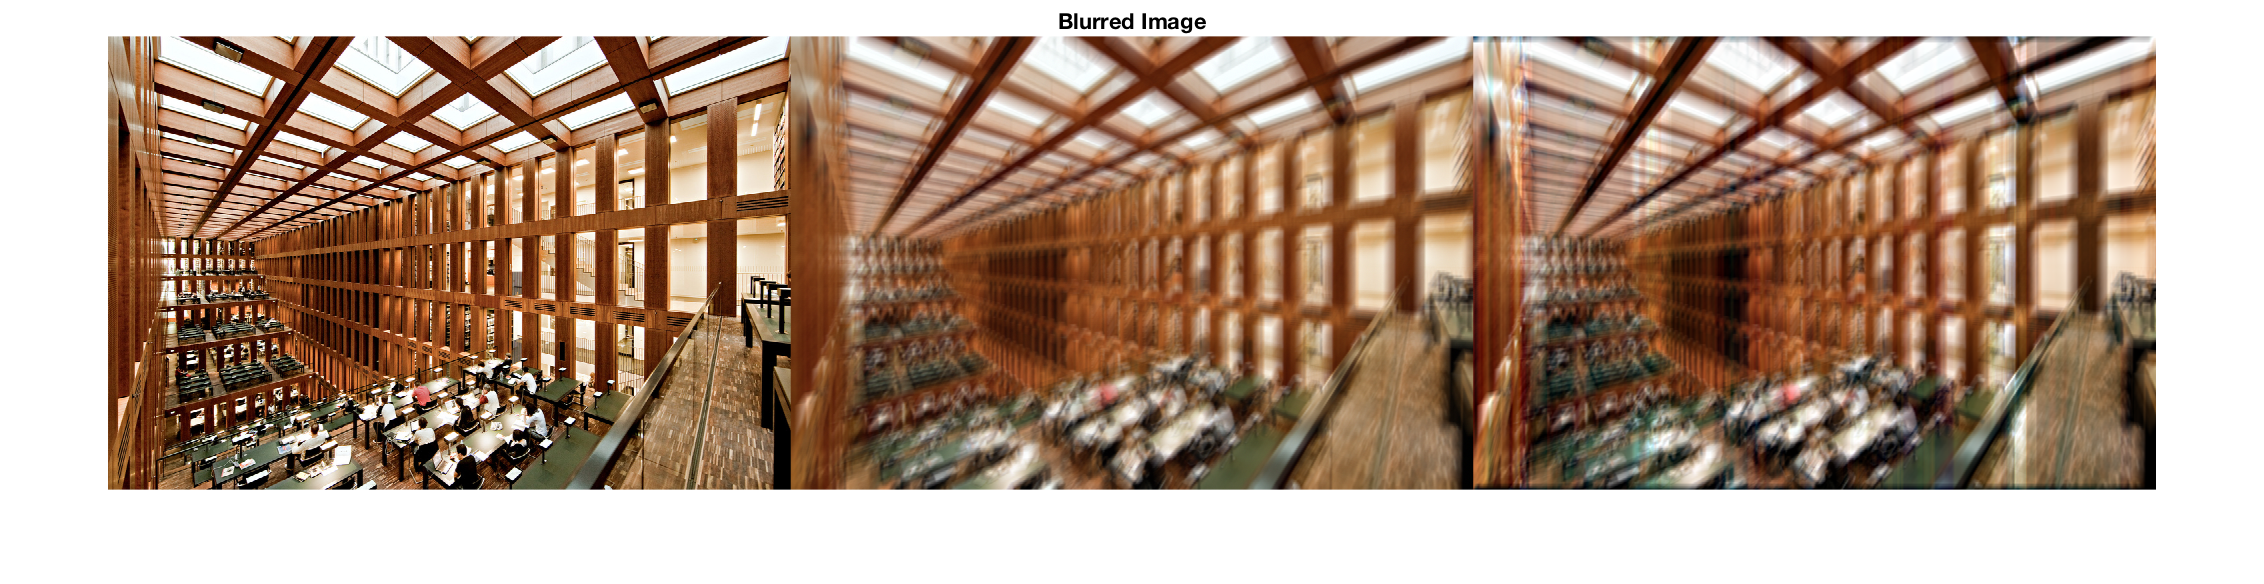

% blurred = imfilter(I, PSF, 'conv', 'circular');

O = im2double(imread('synthetic_data/uniform/manmade_01_kernel_01.png'));
imshow([I, O, Nr]);
title('Blurred Image');